model_A = model(10, ...
    [repelem(1, 2, 1); repelem(10, 5, 1); repelem(100, 3, 1)], ...
    [repelem(2, 2, 1); repelem(1, 5, 1); repelem(0.5, 3, 1)] ...
    );

homophily_A = model_A;
homophily_A.A = ones(homophily_A.N);
homophily_A.A(1:2, 3:10) = 0;
homophily_A.A(3:7, [1:2 8:10]) = 0;
homophily_A.A(8:10, 1:7) = 0;
homophily_A = homophily_A.network;
homophily_A = homophily_A.monte_carlo(5000);

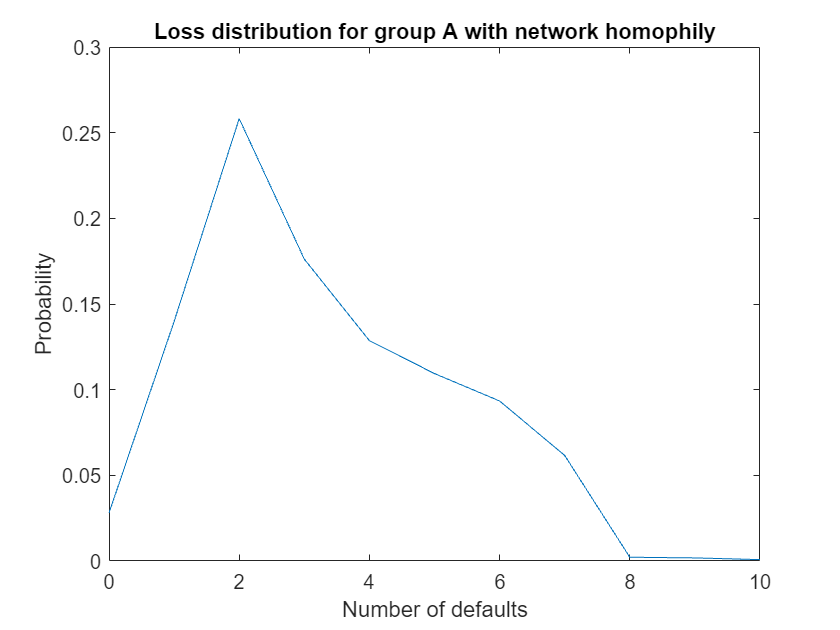

homophily_A.plot_loss;
title('Loss distribution for group A with network homophily');

fprintf("Probability of systemic failure: %.2f", homophily_A.probfail);

Probability of systemic failure: 0.05

heterophily_A = model_A;
heterophily_A.A = ones(heterophily_A.N);
heterophily_A.A(1:2, 1:2) = 0;
heterophily_A.A(3:7, 3:7) = 0;
heterophily_A.A(8:10, 8:10) = 0;
heterophily_A = heterophily_A.network;
heterophily_A = heterophily_A.monte_carlo(5000);

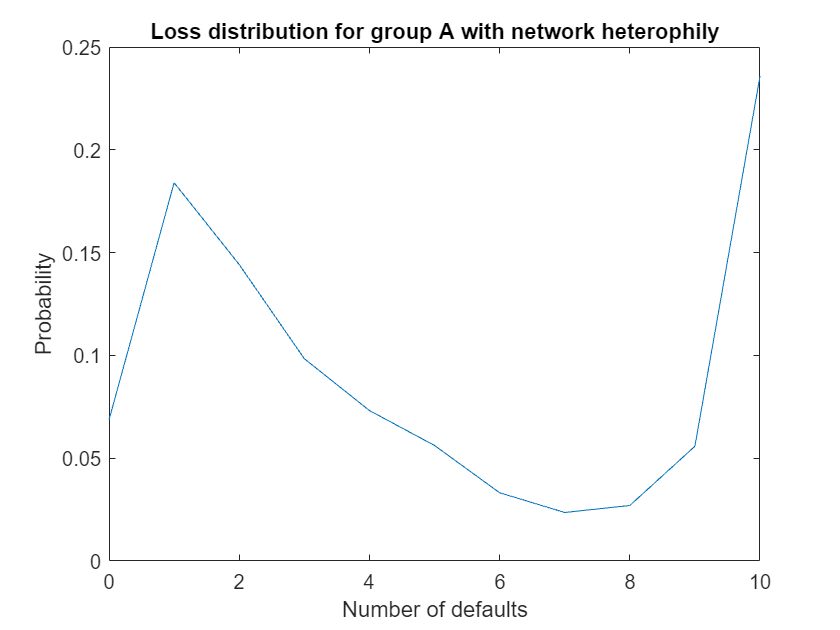

heterophily_A.plot_loss;
title('Loss distribution for group A with network heterophily');

fprintf("Probability of systemic failure: %.2f", heterophily_A.probfail);

Probability of systemic failure: 0.32

model_B = model(10, ...
    [repelem(1, 2, 1); repelem(10, 5, 1); repelem(100, 3, 1)], ...
    [repelem(0.5, 2, 1); repelem(1, 5, 1); repelem(2, 3, 1)] ...
    );

homophily_B = model_B;
homophily_B.A = ones(homophily_B.N);
homophily_B.A(1:2, 3:10) = 0;
homophily_B.A(3:7, [1:2 8:10]) = 0;
homophily_B.A(8:10, 1:7) = 0;
homophily_B = homophily_B.network;
homophily_B = homophily_B.monte_carlo(5000);

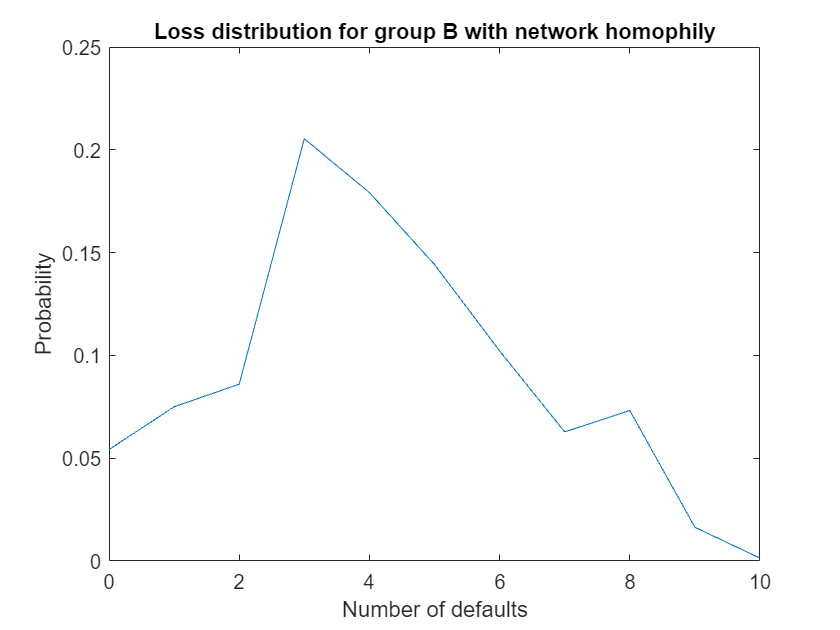

homophily_B.plot_loss;
title('Loss distribution for group B with network homophily');

fprintf("Probability of systemic failure: %.2f", homophily_B.probfail);

Probability of systemic failure: 0.09

heterophily_B = model_B;
heterophily_B.A = ones(heterophily_B.N);
heterophily_B.A(1:2, 1:2) = 0;
heterophily_B.A(3:7, 3:7) = 0;
heterophily_B.A(8:10, 8:10) = 0;
heterophily_B = heterophily_B.network;
heterophily_B = heterophily_B.monte_carlo(5000);

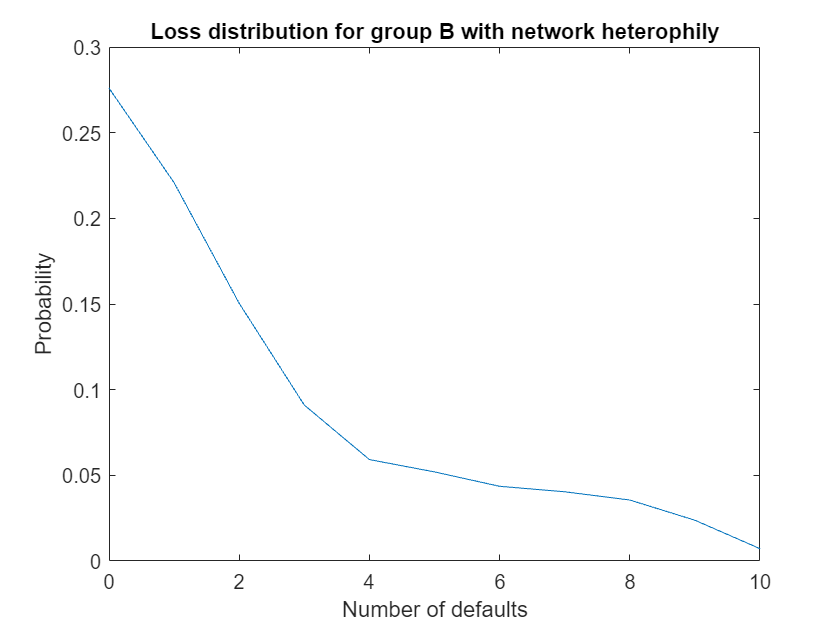

heterophily_B.plot_loss;
title('Loss distribution for group B with network heterophily');

fprintf("Probability of systemic failure: %.2f", heterophily_B.probfail);

Probability of systemic failure: 0.02